# TP 1 

# Partie 1 rappels sur les TF

## Question 1

### Vérifier que la TF d'une fonction porte 2D est un produit de sinus cardinal. Pour cela :

Crééer l'image fonction porte 2D sur une image au format 256x256, dont les 30x30 pixels centraux sont blancs :

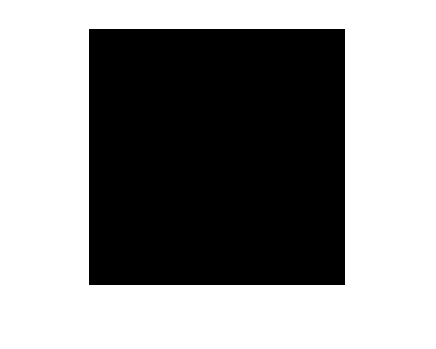

% Création de l'image noire 256x256, utiliser la fonction zeros()
n=256;

% Mise en blanc des pixels centraux 
im=zeros(n);
figure, imshow(im)

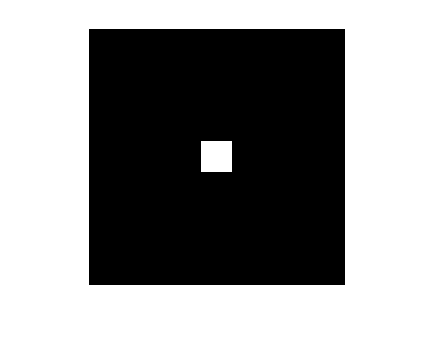

im(n/2-15:n/2+15,n/2-15:n/2+15)=1;
% Affichage de l'image, utiliser la fonction imshow()
figure, imshow(im)

Calculer  et afficher la TF2D de cette image :

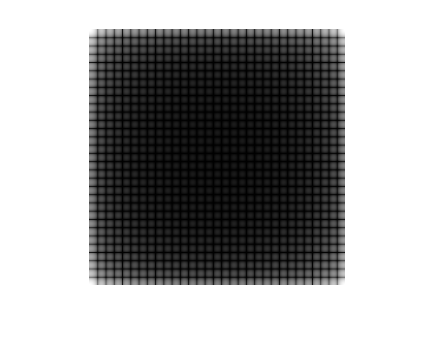

% Calcul de la TF de I, utiliser la fonction fft2()
TF=fft2(im);
% Calcul du module TF de I, utiliser la fonction abs()
M_TF=abs(TF);
% Normalisation du log du module de la TF pour améliorer le rendu
M_TF=log(M_TF+1); % +1 pour éviter log(0)
M_TF= M_TF/max(M_TF(:)); % normaliser entre 0 et 1
% Affichage du module de la TFI
imshow(M_TF)

Recalage de la TF2D à l'aide de fftshift() :

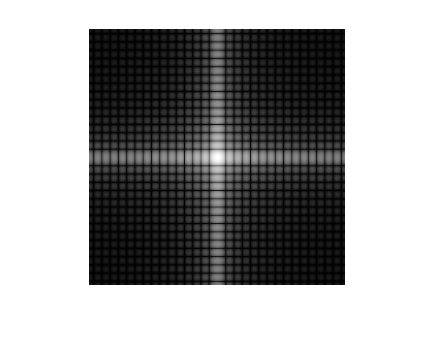

% Décalage de la TF avec fftshift()
TF_shift= fftshift (TF);
% Calcul du module TF de I, utiliser la fonction abs()
M_TF_shift = abs(TF_shift);
% Normalisation du log du module de la TF pour améliorer le rendu
M_TF_shift = log(M_TF_shift+1);
M_TF_shift = M_TF_shift/max(M_TF_shift(:)); 
% Affichage du module de la TFI
imshow(M_TF_shift)

## Ou plus simplement

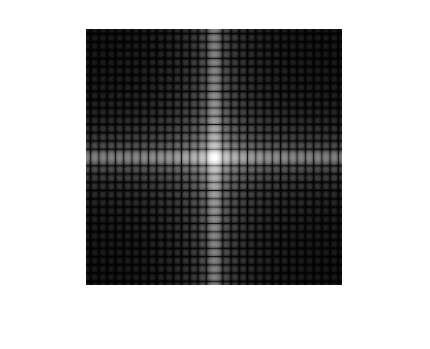

M_TF_shift=fftshift(M_TF);
imshow(M_TF_shift)

Afficher le profil de pixel 1D pour  u=0  (sur le module TF sans normalisation):

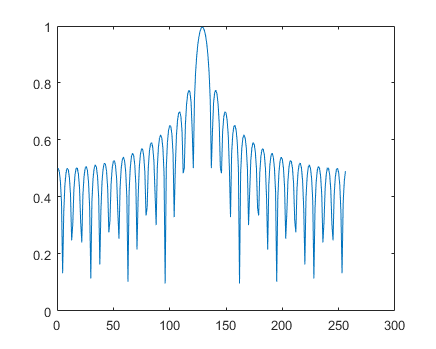


%% afficher avec normalisation 
% Extraction des lignes de pixel u=0
profil = M_TF_shift(n/2,:);
% Affichage à l'aide de plot()
plot(profil)

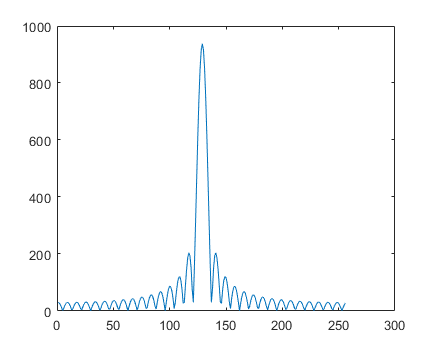


%afficher sans normalisation
TF=fftshift(fft2(im));
% Calcul du module TF de I, utiliser la fonction abs()
M_TF=abs(TF);
profil = M_TF(n/2,:);
% Affichage à l'aide de plot()
plot(profil)

## Question 2

### Que devient la TF pour d'autres largeurs de la fonction porte? Pour cela :

Faire une boucle parcourant la liste taille=[30 60 90 120], qui affiche pour chaque largeur de la fonction porte, l'image de la fonction porte 2D, le module de la TF2D et le profil u=0.

% Boucle 
taille = [30 60 90 120]

taille =     30    60    90   120


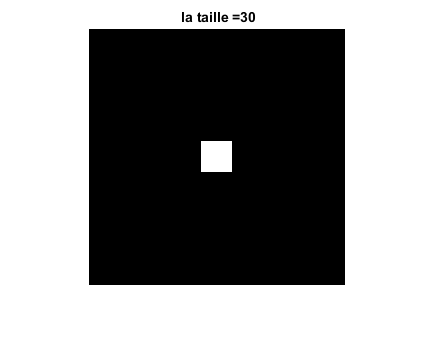

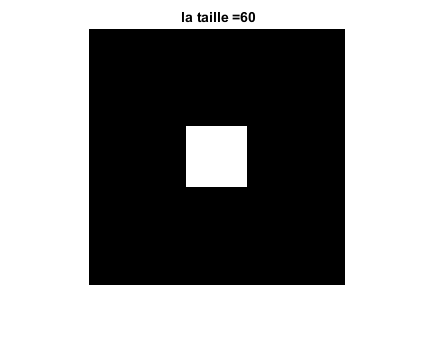

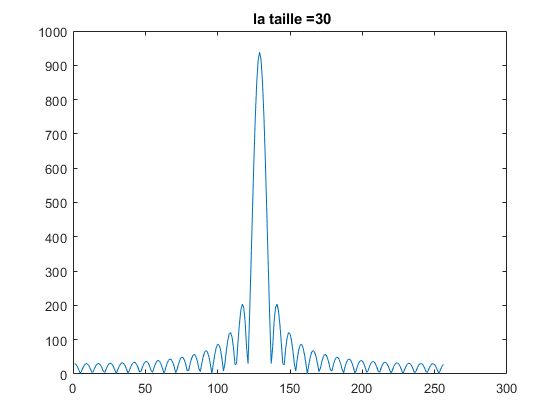

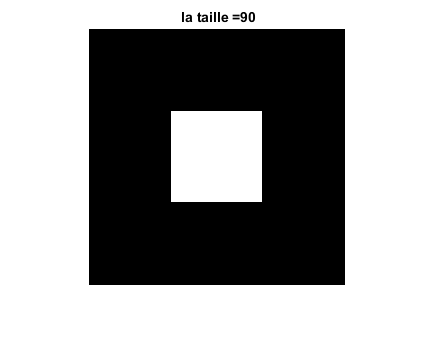

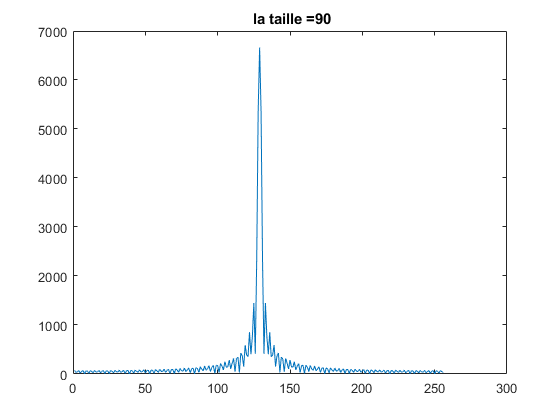

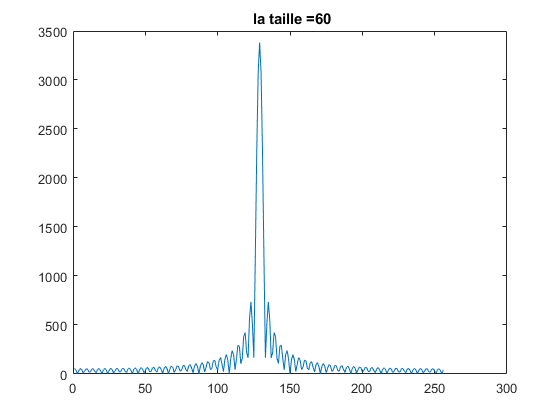

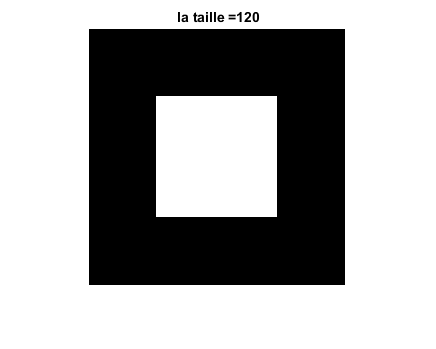

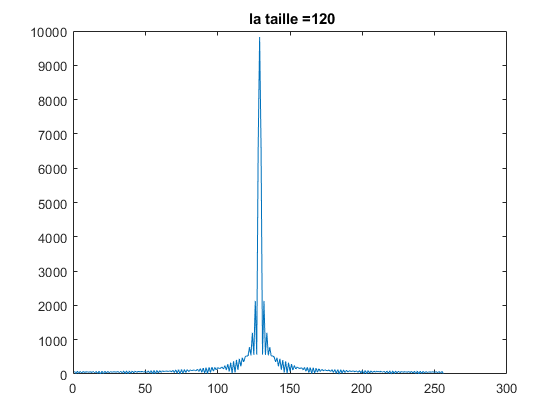

n=256;
for i = taille
    im= zeros(n);
    im(n/2-i/2:n/2+i/2,n/2-i/2:n/2+i/2)=1;
    figure,imshow(im)
    title(' la taille ='+string(i))
    TF=fftshift(fft2(im));
    M_TF= abs(TF);
    profil= M_TF(n/2,:);
    figure, plot(profil)
    title(' la taille ='+ string(i))
end

Coment évolue la TF2D avec la largeur de la fonction porte 2D ?

 TF2D= tho* sinc(pi*u*tho), plus la largeur est grande, plus son module de TF est grand, plus sa fréquence de sin est grande  

## Question 3 

### Quelle est la TF d'une fonction sinus ?  Vérifier ce résultat grace à Matlab. Pour cela :

Créer une image au format 256x256 présentant une évolution d'intensité sinusoïdale selon la direction des lignes :

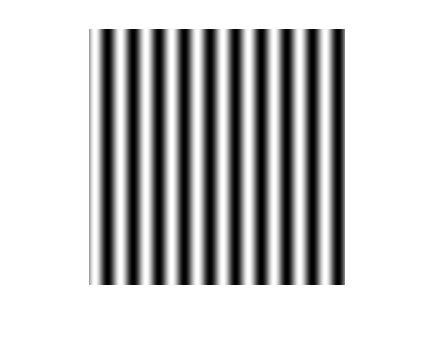

% Création de l'image noire 256x256, utiliser la fonction zeros()
n=256;
im=zeros(n);

% Evolution sinusoïdale de l'intensité à l'aide d'une boucle
y=1:256;
f=10; % f=10Hz
for x = 1:n
    im(x,:)= sin(2*pi*f*y/n);
end

% Affichage de l'image, utiliser la fonction imshow()
figure, imshow(im,[min(im(:)),max(im(:))])

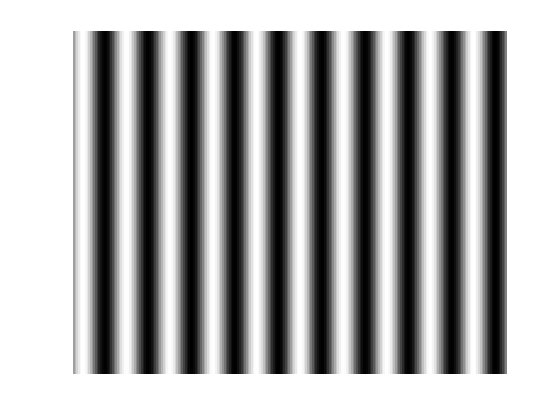

% ou utiliser imagesc() sans préciser l'intervalle de l'affichage 
figure, colormap('gray')
imagesc(im),axis off

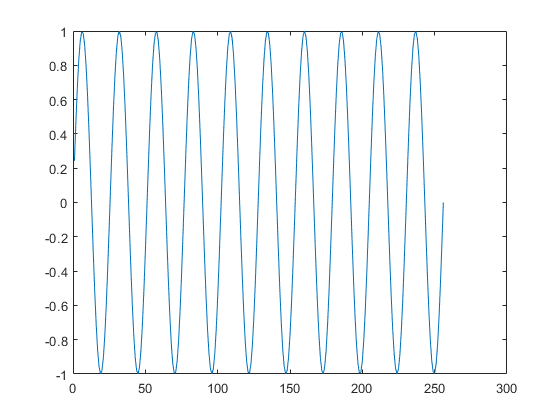


% Affichage du profil sur une ligne de pixel horizontale 
profil = im(n/2,:);
figure, plot(profil)

Calculer et afficher le module de la TF2D centré de cette image :

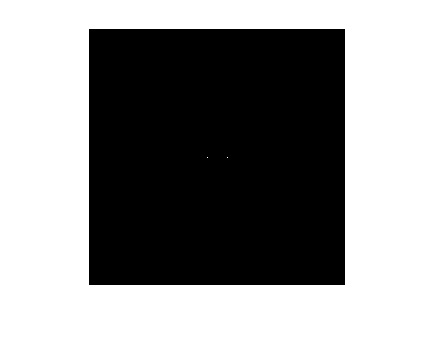

% Calcul du module TF de I, utiliser la fonction abs()
TF= fftshift(fft2(im));
M_TF=abs(TF);
% Normalisation du log du module de la TF pour améliorer le rendu
M_TF= log(M_TF+1);
M_TF= M_TF/max(M_TF(:));

%seuil à 0.9 sur P % pas obligatoire si ton sinus est propre
M_TF(M_TF<0.9)=0;

% Affichage du module de la TFI
figure,imshow(M_TF)

Pourquoi y'a t'il un point central ?

Il n'y a pas de point central ici, mais si on ajoute un composant continu dans notre signal, par exemple sin(2*pi*f*y/n)+1, on verra bien un point central 

% Evolution sinusoïdale de l'intensité à l'aide d'une boucle
y=1:256;
f=10; % f=10Hz
for x = 1:n
    im(x,:)= sin(2*pi*f*y/n)+1;
end

% Affichage de l'image, utiliser la fonction imshow()
figure, imshow(im,[min(im(:)),max(im(:))])

% ou utiliser imagesc() sans préciser l'intervalle de l'affichage 
figure, colormap('gray')
imagesc(im),axis off

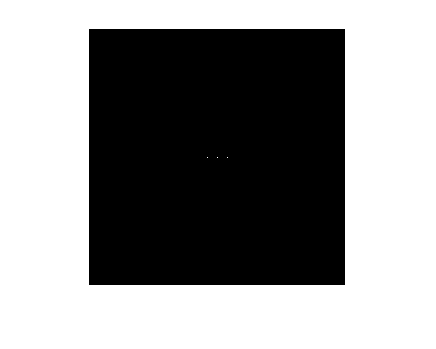


% Calcul du module TF de I, utiliser la fonction abs()
TF= fftshift(fft2(im));
M_TF=abs(TF);
% Normalisation du log du module de la TF pour améliorer le rendu
M_TF= log(M_TF+1);
M_TF= M_TF/max(M_TF(:));

%seuil à 0.9 sur P % pas obligatoire si ton sinus est propre
M_TF(M_TF<0.9)=0;

% Affichage du module de la TFI
figure,imshow(M_TF)

## Question 4

### Que devient la TF2D pour d'autres fréquences ? Pour cela :

Faire une boucle parcourant la liste fréquence=[20 40 60 80], qui affiche pour chaque fréquence de la fonction sinus, l'image de la fonction sinus 2D ainsi que la TF2D de cette dernière.

% liste fréquences
f= [20 40 60 80]

f =     20    40    60    80


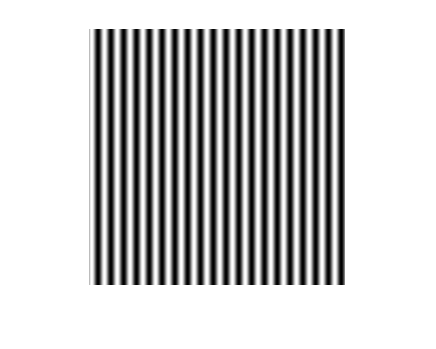

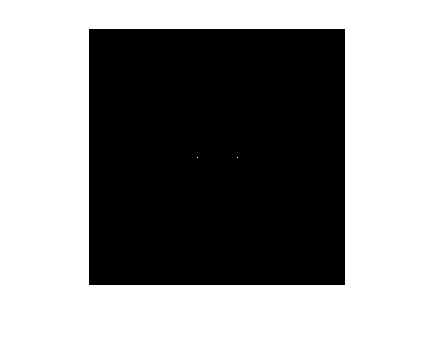

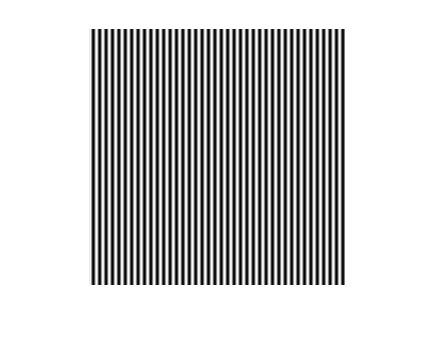

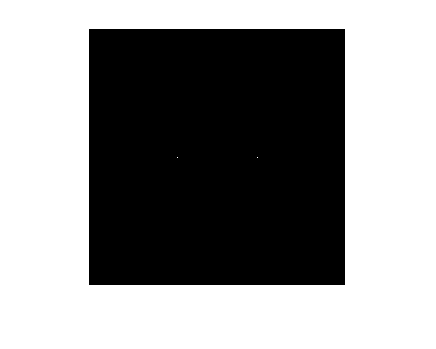

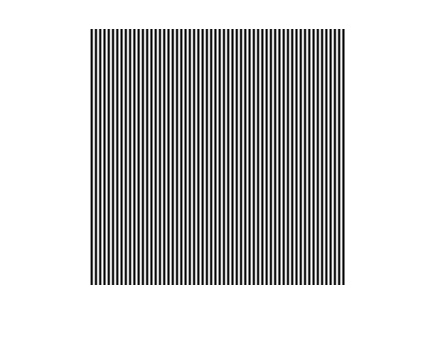

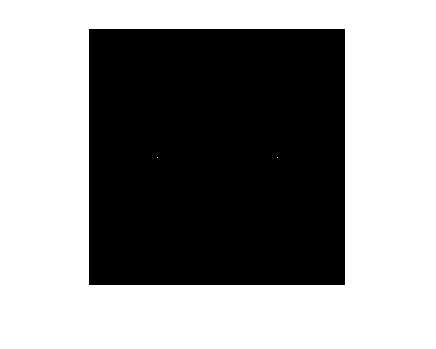

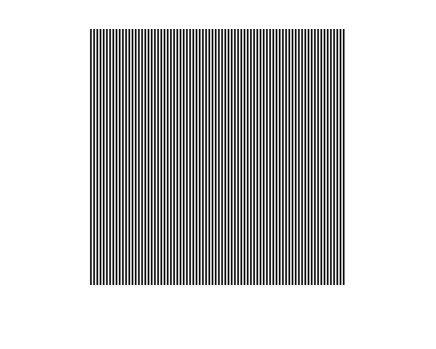

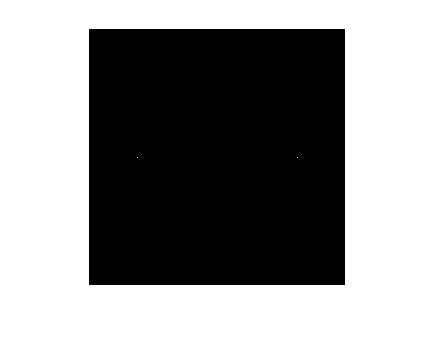

% Création de l'image noire 256x256, utiliser la fonction zeros()
n=256;
im=zeros(n);

% Evolution sinusoïdale de l'intensité à l'aide d'une boucle
y=1:256;
for f=[20 40 60 80]; % f=10Hz
    for x = 1:n
        im(x,:)= sin(2*pi*f*y/n);
    end
    figure, imshow(im,[min(im(:)),max(im(:))])
    
    TF= fftshift(fft2(im));
    M_TF=abs(TF);
    % normalisation
    M_TF=log(M_TF+1);
    M_TF=M_TF/max(M_TF(:));
    figure, imshow(M_TF)

end

# Partie 2 

# Quelques opérations simples sur les images

## Question 5

### Afficher la TF de l'image "Lena.jpg". Pour cela :

Charger l'image :

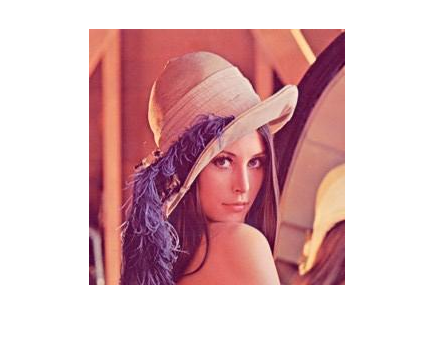

% utiliser imread()
im=imread("Lena.jpg");
% afficher l'image en couleur
imshow(im)


disp(size(im))

   256   256     3



Pourquoi y'a t'il 3 canaux ?  Image RGB (Red, Green, Blue)

Convertir l'image en niveaux de gris :

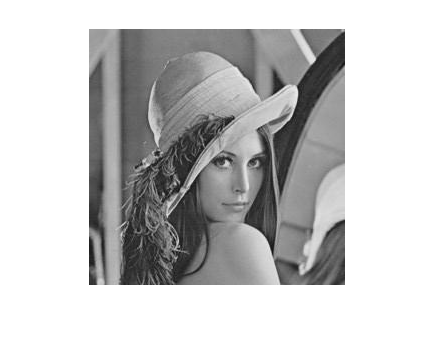

% utiliser rgb2gray()
im_gris= rgb2gray(im);
% afficher l'image en niveaux de gris
imshow(im_gris)

Calculer et afficher sa TF :

% Calcul de la TF centrée de l'image en niveaux de gris

% Normalisation du log du module de l TF pour améliorer le rendu


% Affichage


## Question 6

### Afficher les images, histogrammes  et entropie des canaux RGB. Pour cela :

Extraire les canaux RGB :

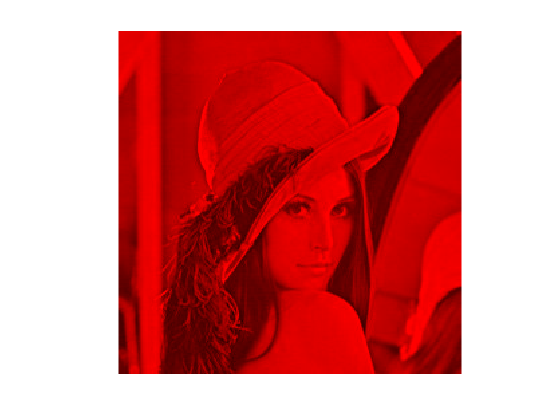

% Stockage des canaux de l'image de Lena :
R= im(:,:,1);
G= im(:,:,2);
B= im(:,:,3);

% image rouge R
im_R=im;
im_R(:,:,2:3)=0; % ne garde que red
imshow(im_R)

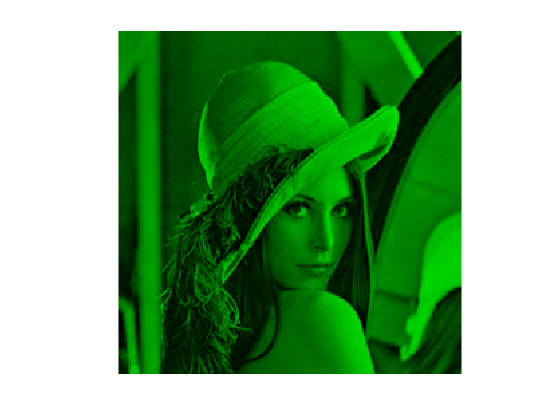


% image vert G
im_G=im;
im_G(:,:,[1 3])=0; % ne garde que Green
imshow(im_G)

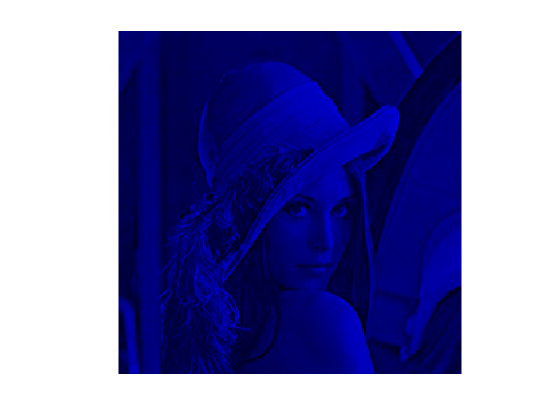

% image Bleu B
im_B=im;
im_B(:,:,1:2)=0; % ne garde que Blue
imshow(im_B)

Calcul des entropies des canaux :

% utiliser la fonction entropy() ou calculer avec la formule du cours :
SR= entropy(R); disp('Entropy of R='+string(SR))

Entropy of R=7.2914


SG= entropy(G); disp('Entropy of G='+string(SG))

Entropy of G=7.5827


SB= entropy(B); disp('Entropy of B='+string(SB))

Entropy of B=7.0765



% ou par la formule du cours S= -sum(p*log2(p),'omitnan') 
% 'omitnan' pour négliger NaN ( quand p=0, log2(p)=NaN )
nb_pixels= 256*256;
pR= imhist(R)/nb_pixels;
pG= imhist(G)/nb_pixels;
pB= imhist(B)/nb_pixels;

SR2= -sum(pR.*log2(pR),'omitnan');disp('Entropy of R2='+string(SR2))

Entropy of R2=7.2914


SG2= -sum(pG.*log2(pG),'omitnan');disp('Entropy of G2='+string(SG2))

Entropy of G2=7.5827


SB2= -sum(pB.*log2(pB),'omitnan');disp('Entropy of B2='+string(SB2))

Entropy of B2=7.0765


Affichage des différents résultats, c'est à dire l'image du canal, l'histogramme et l'entropie :

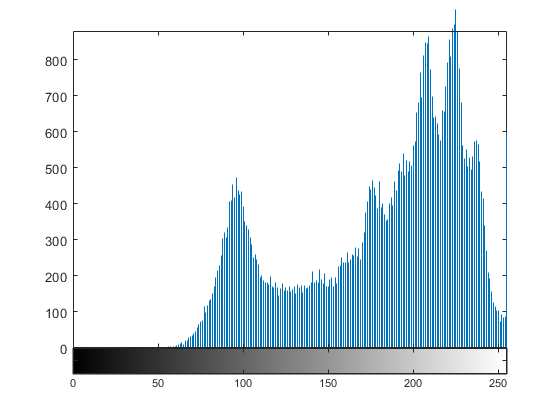

%canal R
figure, imhist(R)

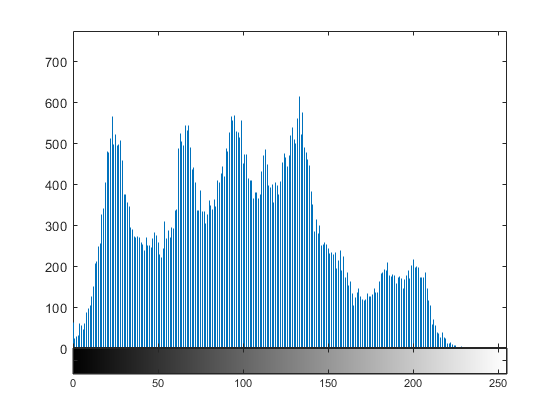

%canal G
figure, imhist(G)

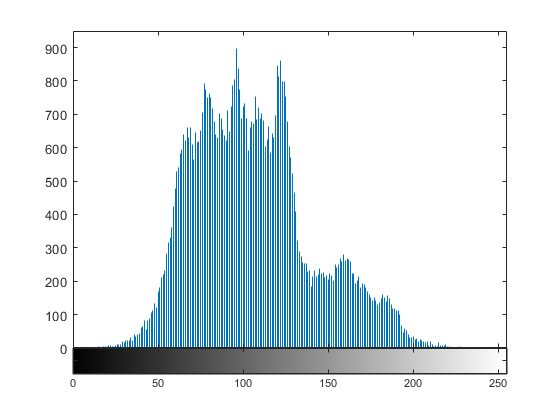

%canal B
figure, imhist(B)

## Question 7

### Afficher les histogrammes 2D de Lena entre les canaux  R et G, puis calculer l'entropie jointe. Réitérer avec le cas particulier de deux bandes identiques B et B. Pour cela :

Créer l'histo 2D des canaux R et G :

% initialisation de l'histo 2D
histo2D=zeros(256);
% double boucle sur tous les pixels
n=256

n = 256

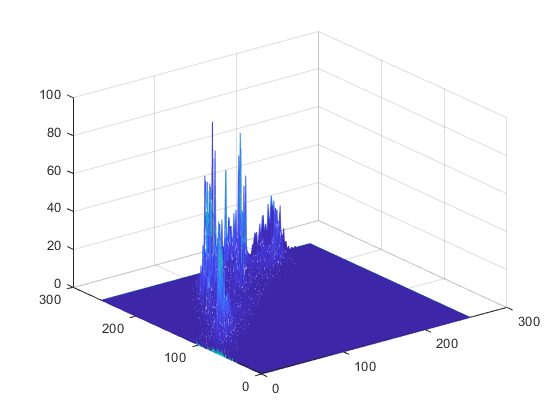

for i=1:n
    for j=1:n
        VR= R(i,j)+1; % valeur de pixel de l'image R
       % +1 pour éviter d'avoir 0 pour index
        VG= G(i,j)+1; % valeur de pixel de l'image G
        histo2D(VR,VG)=histo2D(VR,VG)+1;
    end
end

figure, meshz(histo2D)

Calculer l'entropie jointe des canaux R et G :

% entropie jointe
pRG= histo2D/nb_pixels;

SRG= -sum(pRG(:).*log2(pRG(:)),'omitnan')

SRG = 12.8365

Afficher les résultats :

% affichage des résultats à l'aide meshz() pour l'histo2D


Créer l'histo 2D des canaux B et B :

% initialisation de l'histo 2D
histo2D=zeros(256);
% double boucle sur tous les pixels
n=256

n = 256

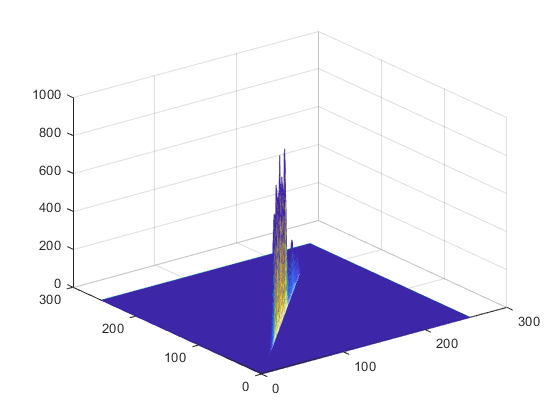

for i=1:n
    for j=1:n
        VB= B(i,j)+1; % valeur de pixel de l'image R
       % +1 pour éviter d'avoir 0 pour index
       
        histo2D(VB,VB)=histo2D(VB,VB)+1;
    end
end

figure, meshz(histo2D)

% entropie jointe
pBB= histo2D/nb_pixels;

SBB= -sum(pBB(:).*log2(pBB(:)),'omitnan')

SBB = 7.0765


SB= entropy(B); disp('Entropy of B='+string(SB))

Entropy of B=7.0765


Calculer l'entropie jointe des canaux B et B :

% entropie jointe à l'aide de la formule du cours


Afficher les résultats

% affichage des résultats



## Question 8

### Afficher l'histogramme et l'entropie de l'image de base de Lena convertie en niveaux de gris, puis réitérer après avoir réduit/augmenter le contraste, et augmenter la brillance. Pour cela :

Convertir l'image initiale en niveaux de gris, calculer son entropie, son histogramme et afficher le tout :

% utiliser imread()
im=imread('Lena.jpg');
% conversion en niveaux de gris
im=rgb2gray(im);
% calcul de l'entropie avec entropy()
S= entropy(im);
% affichage histogramme, image et entropie
figure, imshow(im)

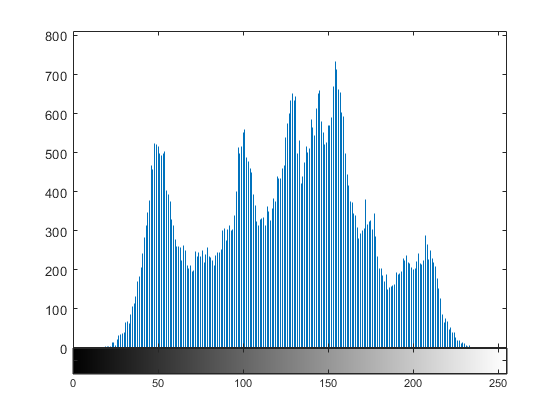

figure, imhist(im)

disp("Entropy is "+ string(S))

Entropy is 7.4579


Réduire le contaste et afficher les nouveaux résultats :

% stockage des min et max d'intensité de lena en niveaux de gris
vmin= min(im(:));
vmax= max(im(:));
% reduire le contraste, utiliser la fonction imadjust()
im_moins= imadjust(im,[vmin/255 vmax/255],[0.3 0.7]);

% calcul de l'entropie avec entropy()
S_im_moins = entropy(im_moins)

S_im_moins = 6.1111

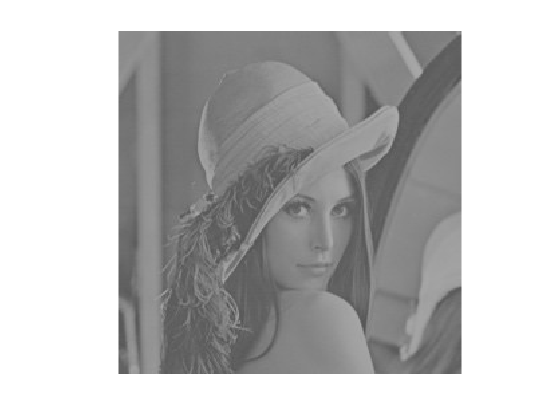

% affichage histogramme, image et entropie
imshow(im_moins)

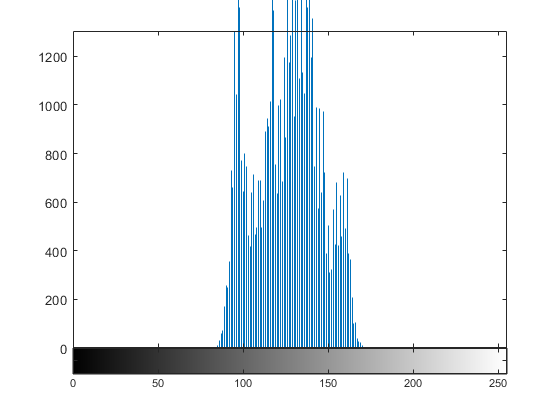

figure,imhist(im_moins)

Augmenter le contraste et afficher les nouveaux résultats :

% augmenter le contraste, utiliser la fonction imadjust()
im_plus= imadjust(im,[vmin/255 vmax/255],[0 1]);

% calcul de l'entropie avec entropy()
S_im_plus = entropy(im_plus)

S_im_plus = 7.4579

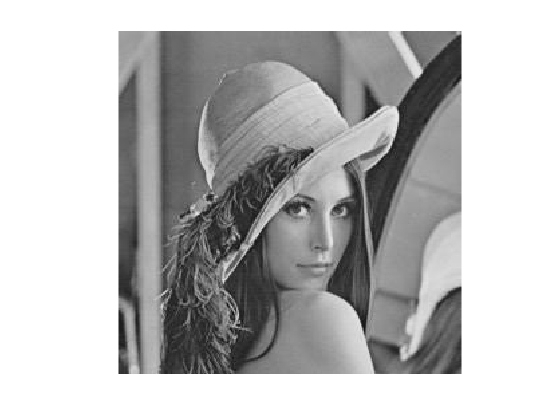

% affichage histogramme, image et entropie
imshow(im_plus)

figure, imhist(im_plus)

Augmenter la brillance et afficher les nouveaux résultats :

% augmenter la brillance, utiliser la fonction imadjust()
im_brillance= imadjust(im,[vmin/255 vmax/255],[0.5 1]);

% calcul de l'entropie avec entropy()
S_im_brillance = entropy(im_brillance)

S_im_brillance = 6.4409

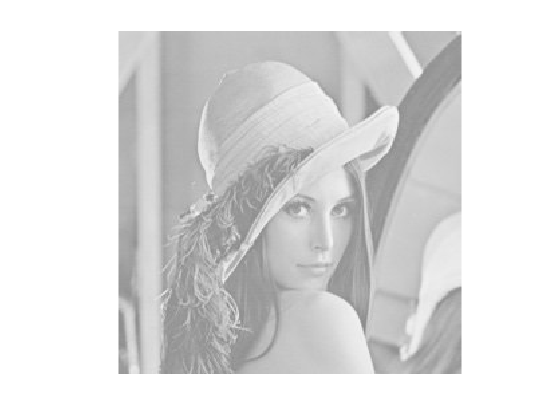

% affichage histogramme, image et entropie

imshow(im_brillance)

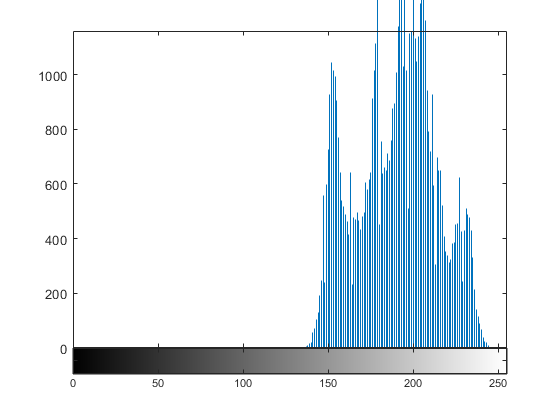

figure, imhist(im_brillance)

## Question 9

### Afficher l'histogramme et l'entropie de l'image de base de Lena convertie en niveaux de gris après avoir égaliser son histogramme. Pour cela :

Utiliser histeq() pour égaliser l'image de Lena en niveaux de gris :

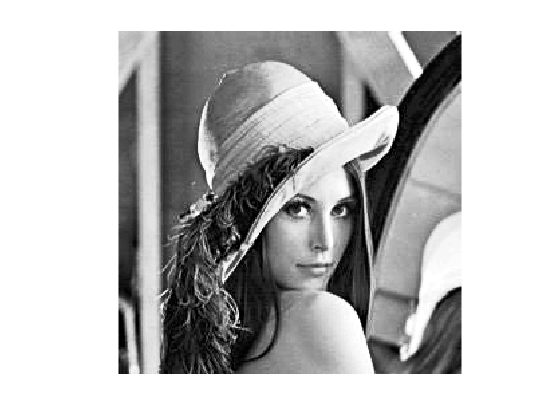

im_eq=histeq(im);
imshow(im_eq)

Afficher la nouvelle image, son nouvel histogramme et sa nouvelle entropie :

% calcul de l'entropie avec entropy()
S_eq= entropy(im_eq)

S_eq = 5.9739

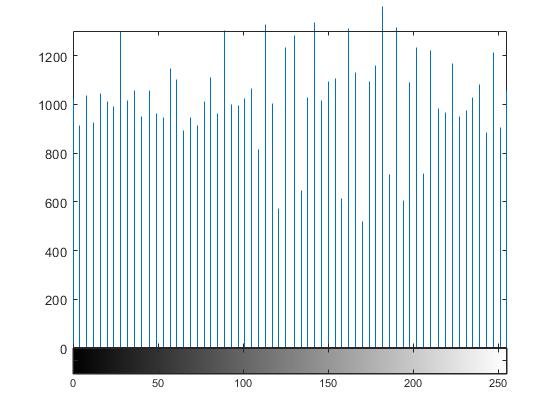

% affichage histogramme, image et entropie
figure
imhist(im_eq)

## Question 10

### A l'aide de la fonction imcomplement(), afficher en vis à vis l'image de Lena, son histogramme, ainsi que leurs homologues avec l'image complémentaire. Pour cela : 

Créer l'image complémentaire : 

im_com= imcomplement(im);

Afficher les images et leurs histogrammes

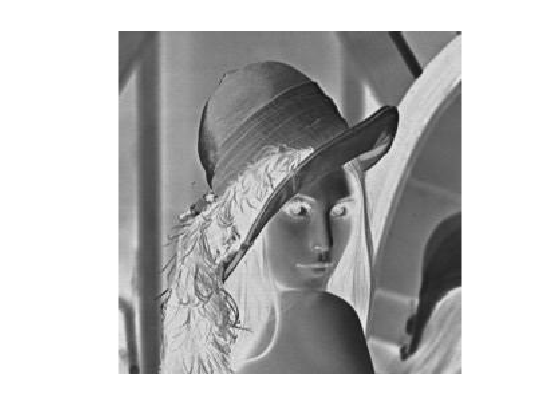

imshow(im_com)

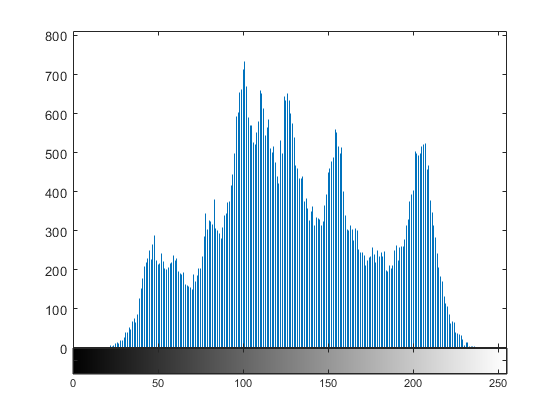

figure, imhist(im_com)

Interpréter les résultats